%{
Linear + Piecewise function
Author: Benjamin Mangani
Version: 2.0
Date: 26-03-2026
Purpose:
    Showcases how costly an electric bill would be depending on usage
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
Engineering Algorithms:
    - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding  
MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
%}

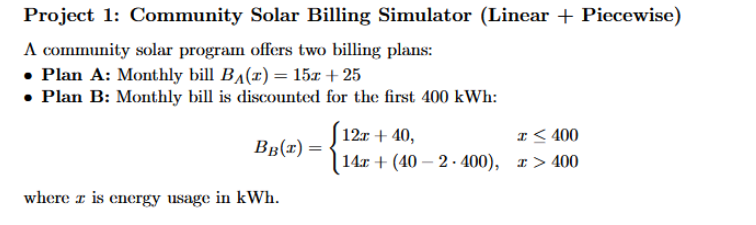

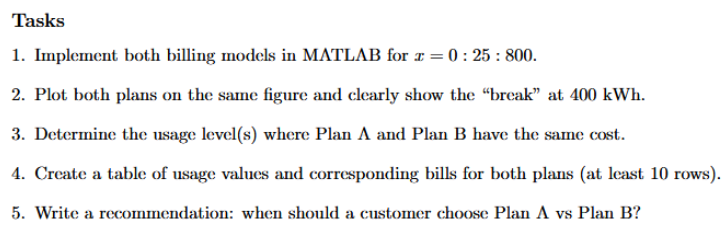

% Define energy usage vector from 0 to 800 in steps of 25 kWh
x = 0:25:800

x =      0    25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500   525   550   575   600   625   650   675   700   725   750   775   800


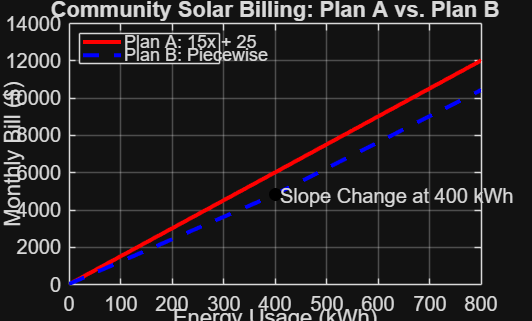

% Define billing for Plan A
BA = 15*x + 25;
% Define billing for Plan B
BB = zeros(size(x));
% Build piecewise billing for Plan B
for i = 1:length(x)
    if x(i) <= 400
        % Lower-rate segment up to 400 kWh
        BB(i) = 12*x(i) + 40;
    else
        % Higher-rate segment above 400 kWh (offset adjusted)
        % Simplified: 14x + (40 - 800) -> 14x - 760
        BB(i) = 14*x(i) - 760;
    end
end
% Plot BA and BB vs x with styling; keep figure open for further edits
figure;
plot(x, BA, 'r-', 'LineWidth', 2); hold on;
plot(x, BB, 'b--', 'LineWidth', 2);
grid on;
% Define a break point in data/axes at x=400 and corresponding y value
x_break = 400;
y_break = 12*400 + 40;
% Mark and label the slope change at the breakpoint
plot(x_break, y_break, 'ko', 'MarkerFaceColor', 'k');
% Annotate a slope-change marker near the break point
text(x_break + 10, y_break - 100, 'Slope Change at 400 kWh', 'FontSize', 10);
% Label x-axis as energy usage in kWh
xlabel('Energy Usage (kWh)');
% Label y-axis as monthly bill in dollars
ylabel('Monthly Bill ($)');
% Title describing the comparison being plotted
title('Community Solar Billing: Plan A vs. Plan B');
% Legend describing the two plotted plans, placed northwest
legend('Plan A: 15x + 25', 'Plan B: Piecewise', 'Location', 'northwest');